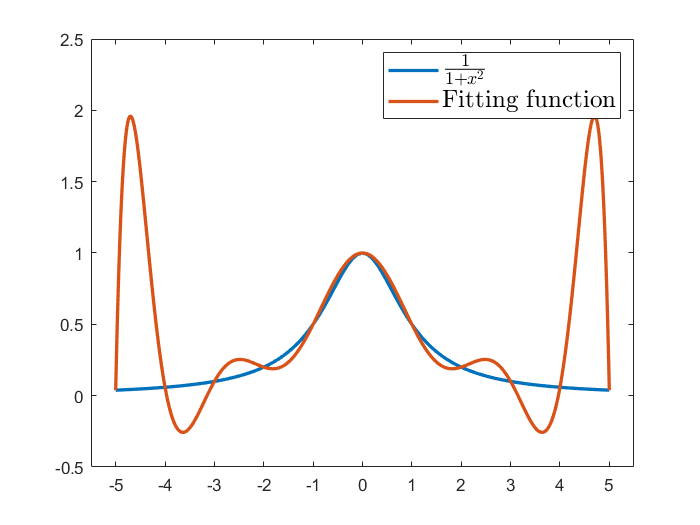

clc,clear,close all
x = -5:0.1:5;
y = 1./(1+x.^2);
plot(x,y,'LineWidth',2)
hold on

x = -5:1:5;
y = 1./(1+x.^2);
xx = -5:0.01:5;
yy = myfun(xx,x,y);
plot(xx,yy,'LineWidth',2)
hold off
h = legend('$\frac{1}{1+x^2}$','Fitting function');
set(h,'Interpreter','latex','FontName','Times New Roman','FontSize',15,'FontWeight','normal') %设置legend为latex解释器显示分式

xlim([-5.5 5.50])
ylim([-0.50 2.50])
f = getframe(gcf);

imwrite(f.cdata, '龙格现象.png');